**Signal Generation and Barlett Algo Function**

function [ESTIMATED_ARRIVAL_ANGLE, MAGP] = BARTLETT_DOA(ARRIVAL_ANGLE)
%%%%%%%%%%%%%%%%%%%%%%%%%% Create hydrophone signals %%%%%%%%%%%%%%%%%%%%%%%%%%
    % Define constants
    fs = 500e3; % sampling freq
    f = 30e3; % frequency of emitted sinusoid (pinger)
    factor = 100; %idk what this is
    over_fs = fs*factor;
    c = 1480;
    lambda = c/f;
    d = c/30e3/2; %lambda/2
    H = 4;
    dd = (0:1:H-1) * d;

    % Delays for each hydrophone in samples
    delay = zeros(H,1);
    for h = 1 : H
        delay(h) = ceil(abs((((h-1) * d * cos(deg2rad(ARRIVAL_ANGLE))) / c) * over_fs))+200;
    end
    
    max_delay = (d * sin(pi/2)) / c; % delay of last HYDRO_SIGNALS if hit endfire
    max_delay_samples = ceil(max_delay * over_fs);
    
    n = 0:1/over_fs:.0001-1/over_fs; % discrete time in samples
    n2 = 0:1/fs:.0001-1/fs;
    N = length(n);
    
    %aa = exp(1j*k*dd*cos(arrival_ang_rad));
    signal = sin(2*pi*f*n); % pinger signal
    
    % HYDRO_SIGNALS ~ (4,length(t)) array, each row is a signal received by each HYDRO_SIGNALSphone
    HYDRO_SIGNALS = zeros(H, N); 
    
    % Set refemic as mic that gets hit first and apply delays accordingly
    if ARRIVAL_ANGLE < 90
        for h = 1 : H
            HYDRO_SIGNALS(H-h+1,:) = sin(2*pi*f*(n-delay(h)*1/over_fs));
        end
        refmic = HYDRO_SIGNALS(H,:);
    else
        for h = 1 : H
            HYDRO_SIGNALS(h,:) = sin(2*pi*f*(n-delay(h)*1/over_fs));
        end
        refmic = HYDRO_SIGNALS(1,:);
    end
    
    % Add noise to signals (random noise for all signals)
    % signalPower = rms(HYDRO_SIGNALS(:,1))^2;
    [HYDRO_SIGNALS_NOISEY, noiseVar] = awgn(HYDRO_SIGNALS,0,'measured'); % 2nd parameter is SNR
    
    HYDRO_SIGNALS_DEC = zeros(H,N/factor);
    for h = 1 : H
        HYDRO_SIGNALS_DEC(h,:) = HYDRO_SIGNALS_NOISEY(h,1:factor:end);
    end

%%%%%%%%%%%%%%%%%%%%%%%%%% Calculate Bartlett Power Spectrum %%%%%%%%%%%%%%%%%%%%%%%%%%
    theta = (0:10:180) * pi / 180; % define angle range
    k = 2*pi/lambda;
    
    a = zeros(H,length(theta)); % allocate space for array manifold
    fourier = zeros(size(HYDRO_SIGNALS_DEC));
    % create array manifold (for each angle in theta, there is a 4x1 steering vector)
    for i=1:length(theta)
        a(:,i) = exp(1j*k*dd*cos(theta(i)));
    end
    
    nn= length(n2);
    
    % Hilbert Transform
    for i = 1 : H
        fourier(i,:) = fft(HYDRO_SIGNALS_DEC(i,:));
        fourier(i,26:nn) = zeros(1,25);
        HYDRO_SIGNALS_DEC(i,:) = ifft(fourier(i,:));
    end
    
    % create R
    R = zeros(H,H); %allocate space for x(t)x(t)^H
    
    for nn = 1 : 50
        R = R + HYDRO_SIGNALS_DEC(:,nn) * HYDRO_SIGNALS_DEC(:,nn)';
    end
    
    R = R / (N/factor);
    
    % Calculate P(theta) for every theta
    P = zeros(1,length(theta));
    MAGP = zeros(1,length(theta));
    
    for i=1:length(theta)
        %P(i) = 1/(a(:,i)'/(R)*a(:,i));
        P(i) = a(:,i)'*R*a(:,i) / (a(:,i)'*a(:,i));
        MAGP(i) = norm(P(i));
    end
    
    [MAX_POWER, I] = max(MAGP);

    ESTIMATED_ARRIVAL_ANGLE =  theta(I) * 180/pi;
end

**Test** **Function**

theta = (0:10:180) * pi / 180; % define angle range
[ang, power] = BARTLETT_DOA(50);
fprintf('Estimated DOA: %d degrees', ang)

Estimated DOA: 50 degrees

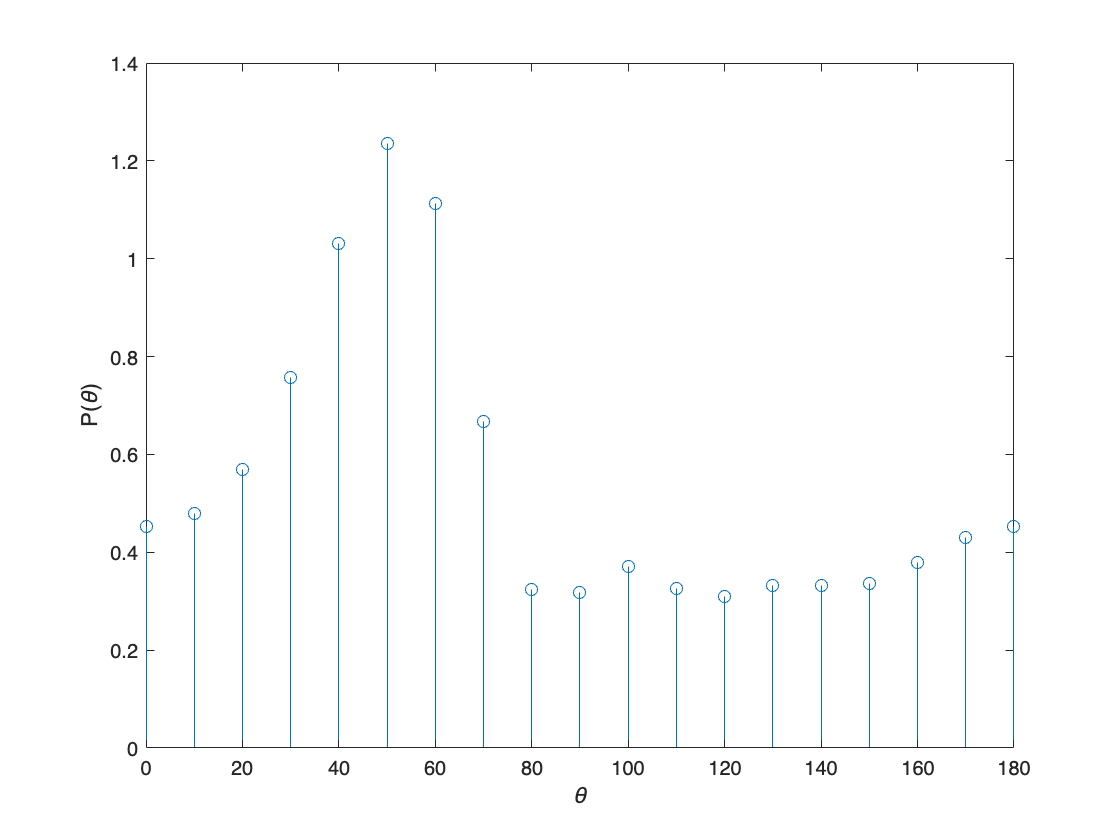

figure;
stem(theta*180/pi,power); 
xlabel('\theta'); ylabel('P(\theta)');

**Noise Robust Test**

% Testing Parameters
all_arrival_angles = 0:10:180; % all possible arrival angles in radians
numTrials = 10;

% Data structure to log estimations of for each arrival angle, for each
% SNR, for each trial.
TestData = repmat(struct('angle', '', 'estimatedAngle', '', 'power', '', 'error', '', 'totalError', 0), 6, 19, numTrials);

% Testing / logging loop
for t = 1:1:numTrials % number of trials
    for i = 0:1:5 % iterate through SNRs
        for j = 1:1:19 % iterate through angles of arrival
            TestData(i+1,j,t).angle = all_arrival_angles(j);
            [TestData(i+1,j,t).estimatedAngle, TestData(i+1,j,t).power] = BARTLETT_DOA(all_arrival_angles(j));
            TestData(i+1,j,t).error = abs(TestData(i+1,j,t).estimatedAngle - TestData(i+1,j,t).angle);
            if t == 1
                TestData(i+1,j,t).totalError = TestData(i+1,j,t).error;
            else
                TestData(i+1,j,t).totalError = TestData(i+1,j,t-1).totalError + TestData(i+1,j,t).error;
            end
        end
    end
end

% Calculate average error for numTrials number of trials
AvgError = 1/numTrials .* arrayfun(@(x) x.totalError, TestData(:,:,numTrials));

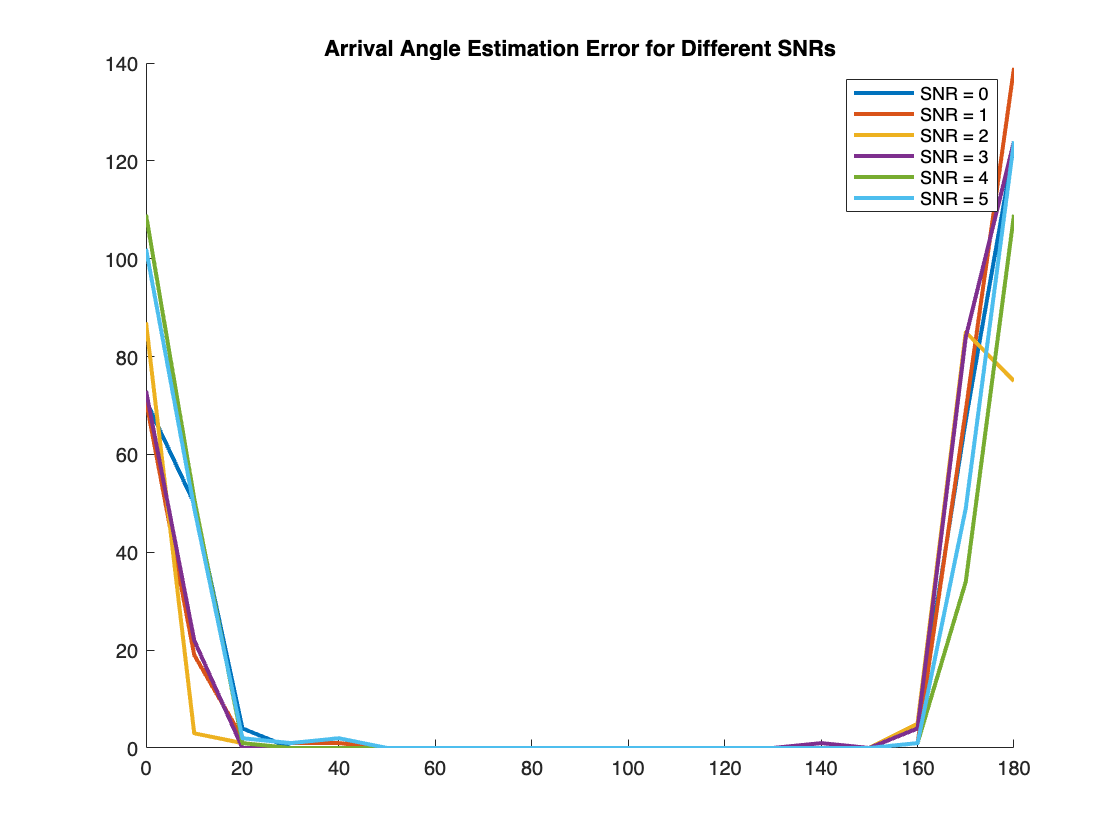

% Plot average errors for each arrival angle for each SNR over all trials
figure;
hold on;
plot(all_arrival_angles,[AvgError(1,:)],'LineWidth',2);
plot(all_arrival_angles,[AvgError(2,:)],'LineWidth',2);
plot(all_arrival_angles,[AvgError(3,:)],'LineWidth',2);
plot(all_arrival_angles,[AvgError(4,:)],'LineWidth',2);
plot(all_arrival_angles,[AvgError(5,:)],'LineWidth',2);
plot(all_arrival_angles,[AvgError(6,:)],'LineWidth',2);
hold off;
title('Arrival Angle Estimation Error for Different SNRs');
legend('SNR = 0','SNR = 1','SNR = 2','SNR = 3','SNR = 4','SNR = 5');
xlim([0,180]); %ylim([0,180]);